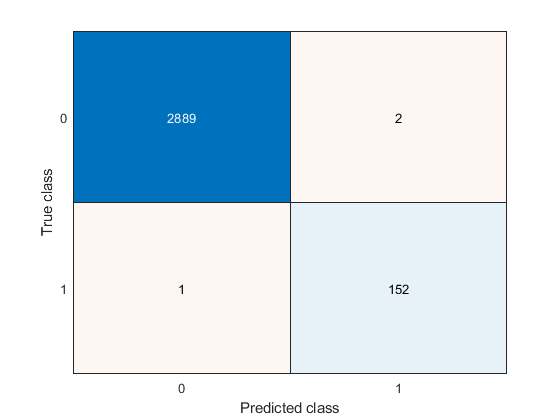

clc;
clear;

% 1. Es creen els dataSets --> executar createDatasets.m (19 segons)

% 2. Fem el training dels ulls --> executar eye_training.m (392 - 2833 segons)

tData = load('data\TrainData.mat');
trainingEyes = tData.trainingEyes;   
trainingNotEyes = tData.trainingNotEyes;

% 3. Fem el testing dels ulls

classifierEyes = load('data\eyeClassifier.mat');
eyeClassifier = classifierEyes.eyeClassifier;
testData = load('data\TestData.mat');
testingEyes = testData.testingEyes;
testingNotEyes = testData.testingNotEyes;

[predictor, cmatrix] = eye_testing();

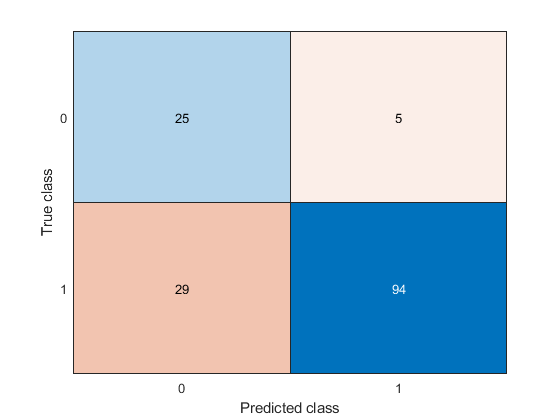


% 4. Fem el training de mirades --> executar gaze_training.m (106 segons)

classifierGaze = load('data\gazeClassifier.mat');
gazeClassifier = classifierGaze.gazeClassifier;
expectedLabels = load('data\GazeLabelsData.mat');
gazeTrainingLabels = expectedLabels.trainigGLab;

% 5. Fem el testing de mirades --> executar gaze_testing.m (6 segons)

gazeTestingLabels = expectedLabels.testingGLab;

[predictor2, cmatrix2] = gaze_testing();